# Final Project

# Mechanical Vibrations

# Instructor : Dr. Arash Bahrami

# Student : Hana Shamsaei

# Student ID : 810600097

## Defining the data given in the project essay

clc,clear,close all 

m = [ 2.294  1.941  1.943  2.732  0.774  0.774] * 1e3;

k = [2155.059  662.275  1455  778.436  75.332  75.332];

kt = 1e5;

L = [10.12 20.21 21.97 25 45.3 45.3];

## Calculating the moment of inertia of masses 5 & 6 to be used as the moment of inertia of the bar connecting them

(Further detail is explained in the project report) 

I = m(5) * L(5) ^ 2 + m(6) * L(6) ^2;

## Defining the mass and stiffness coefficient matrices to obtain the natural frequencies and modeshapes

M = [m(1) 0 0 0 0 0 0

    0 m(2) 0 0 0 0 0

    0 0 m(3) 0 0 0 0

    0 0 0 m(4) 0 0 0

    0 0 0 0 m(5) 0 0

    0 0 0 0 0 m(6) 0

    0 0 0 0 0 0 I];


K = [k(1)+k(2) -k(2) 0 0 0 0 0

    -k(2) k(2)+k(3) -k(3) 0 0 0 0

    0 -k(3) k(3)+k(4) -k(4) 0 0 0

    0 0 -k(4) k(4)+k(5)+k(6) -k(5) -k(6) k(5)*L(5)-k(6)*L(6)

    0 0 0 -k(5) k(5) 0 -k(5)*L(5)

    0 0 0 -k(6) 0 k(6) k(6)*L(6)

    0 0 0 k(5)*L(5)-k(6)*L(6) -k(5)*L(5) k(6)*L(6) k(5)*L(5)^2+k(6)*L(6)^2+kt];

C = 0.005 * K;


## Defining the forces

w = 1.75; 


tspan = 0:0.1:50; 


tf = tspan; 


g = sin(w*tf); 


F = [306.25 

    612.5 

    918.75 

    1225 

    0 

    0
    
    0]; 


## Obtaining natural frequencies and mode shapes

[V , D] = eig(K , M); 

ModeShapes = V

ModeShapes =    -0.0000   -0.0015    0.0021    0.0000    0.0055    0.0191   -0.0059
   -0.0000   -0.0063    0.0081    0.0000    0.0134   -0.0005    0.0152
   -0.0000   -0.0081    0.0092    0.0000    0.0077   -0.0086   -0.0152
   -0.0000   -0.0108    0.0082    0.0000   -0.0129    0.0027    0.0027
    0.0194   -0.0175   -0.0182   -0.0165    0.0030   -0.0002   -0.0001
   -0.0194   -0.0175   -0.0182    0.0165    0.0030   -0.0002   -0.0001
    0.0004   -0.0000   -0.0000    0.0004    0.0000   -0.0000   -0.0000



omega_n = sqrt(D)  

omega_n =     0.1203         0         0         0         0         0         0
         0    0.1928         0         0         0         0         0
         0         0    0.3756         0         0         0         0
         0         0         0    0.4601         0         0         0
         0         0         0         0    0.7220         0         0
         0         0         0         0         0    1.1115         0
         0         0         0         0         0         0    1.4038


## Plotting the mode shapes

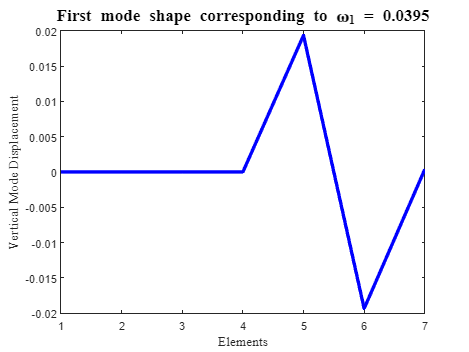

plot(ModeShapes(:,1) , 'color' , "b" , 'LineWidth' , 3)
title("First mode shape corresponding to \omega_1 = 0.0395",'fontName','Times New Roman','FontSize', 15)
ylabel("Vertical Mode Displacement",'fontName','Times New Roman' ,'FontSize', 12)
xlabel("Elements",'fontname','Times New Roman' ,'FontSize', 12)

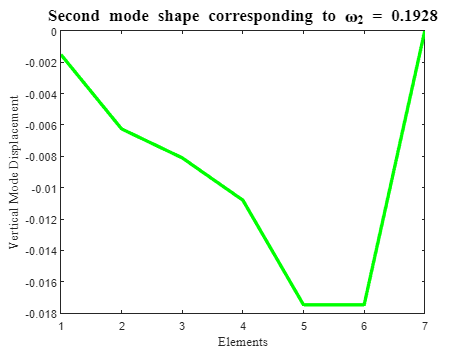


plot(ModeShapes(:,2) , "color" , "g" , 'LineWidth' , 3)
title("Second mode shape corresponding to \omega_2 = 0.1928",'fontName','Times New Roman','FontSize', 15)
ylabel("Vertical Mode Displacement",'fontName','Times New Roman' ,'FontSize', 12)
xlabel("Elements",'fontname','Times New Roman' ,'FontSize', 12)

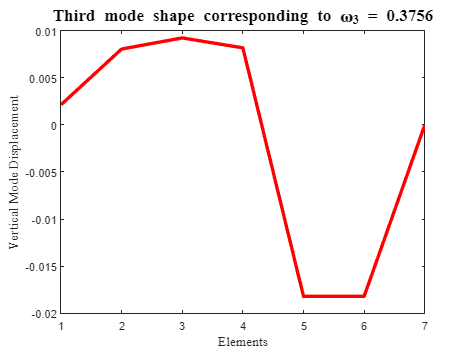


plot(ModeShapes(:,3) , "color" , "r" , 'LineWidth' , 3)
title("Third mode shape corresponding to \omega_3 = 0.3756",'fontName','Times New Roman','FontSize', 15)
ylabel("Vertical Mode Displacement",'fontName','Times New Roman' ,'FontSize', 12)
xlabel("Elements",'fontname','Times New Roman' ,'FontSize', 12)

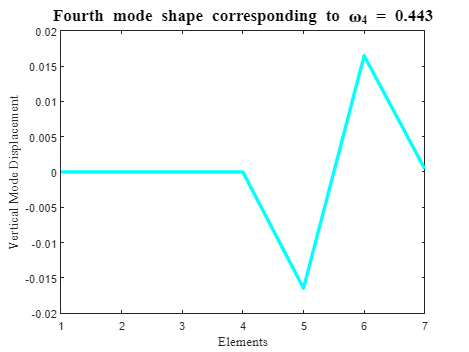


plot(ModeShapes(:,4) , "color" , "c" , 'LineWidth' , 3)
title("Fourth mode shape corresponding to \omega_4 = 0.443",'fontName','Times New Roman','FontSize', 15)
ylabel("Vertical Mode Displacement",'fontName','Times New Roman' ,'FontSize', 12)
xlabel("Elements",'fontname','Times New Roman' ,'FontSize', 12)

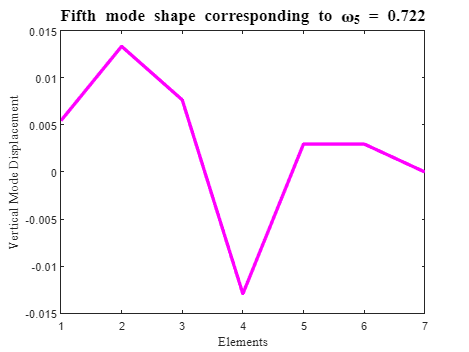


plot(ModeShapes(:,5) , "color" , "m" , 'LineWidth' , 3)
title("Fifth mode shape corresponding to \omega_5 = 0.722",'fontName','Times New Roman','FontSize', 15)
ylabel("Vertical Mode Displacement",'fontName','Times New Roman' ,'FontSize', 12)
xlabel("Elements",'fontname','Times New Roman' ,'FontSize', 12)

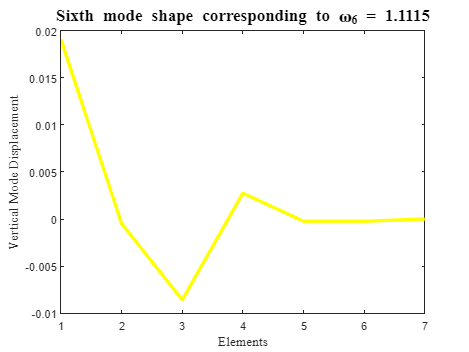


plot(ModeShapes(:,6) , "color" , "y" , 'LineWidth' , 3)
title("Sixth mode shape corresponding to \omega_6 = 1.1115",'fontName','Times New Roman','FontSize', 15)
ylabel("Vertical Mode Displacement",'fontName','Times New Roman' ,'FontSize', 12)
xlabel("Elements",'fontname','Times New Roman' ,'FontSize', 12)

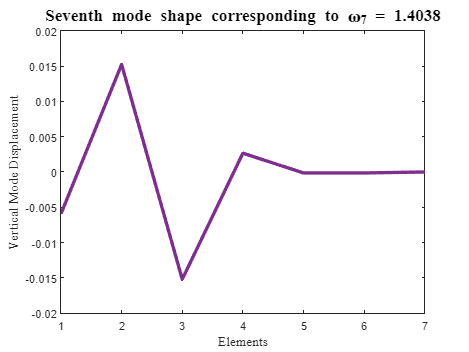


plot(ModeShapes(:,7) , "color" , [0.494, 0.1840, 0.556] , 'LineWidth' , 3)
title("Seventh mode shape corresponding to \omega_7 = 1.4038",'fontName','Times New Roman','FontSize', 15)
ylabel("Vertical Mode Displacement",'fontName','Times New Roman' ,'FontSize', 12)
xlabel("Elements",'fontname','Times New Roman' ,'FontSize', 12)

## Defining the initial conditions and defining the forced response of the system using ode45

x0 = [ 0 0 0 0 0 0 8*pi/180 0 0 0 0 0 0 0]; 

opts = odeset('RelTol',1e-2,'AbsTol',1e-4); 

[t,x] = ode45(@(t,x) odefcn(t , x , M , K , C , tf , g , F) , tspan , x0 , opts); 


## Plotting the force response of the system all together

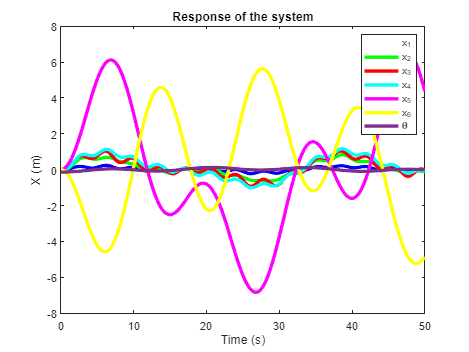

plot(t,x(:,1) , 'color' , "b" , 'LineWidth' , 3) 
hold on
plot(t,x(:,2) , "color" , "g" , 'LineWidth' , 3) 
plot(t,x(:,3) , "color" , "r" , 'LineWidth' , 3) 
plot(t,x(:,4) , "color" , "c" , 'LineWidth' , 3) 
plot(t,x(:,5) , "color" , "m" , 'LineWidth' , 3) 
plot(t,x(:,6) , "color" , "y" , 'LineWidth' , 3) 
plot(t,-x(:,7) , "color" , [0.494, 0.1840, 0.556] , 'LineWidth' , 3) 
title("Response of the system") 
ylabel("X (m)") 
xlabel("Time (s)") 
legend(["x_1","x_2","x_3","x_4","x_5","x_6","\theta"]) 
hold off

## Comparing results from ODE45 and Adams 

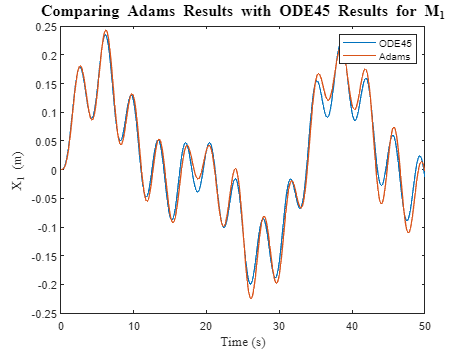

x1 = load('x_m1_adams.mat');
t1 = load('t_m1_adams.mat');
plot(t1.t_m1_adams , x1.x_m1_adams)
hold on
plot(t,x(:,1)) 
hold off
legend('ODE45','Adams')
ylabel("X_1 (m)",'fontName','Times New Roman' ,'FontSize', 12) 
xlabel("Time (s)",'fontName','Times New Roman' ,'FontSize', 12) 
title('Comparing Adams Results with ODE45 Results for M_1','fontName','Times New Roman','FontSize', 14)

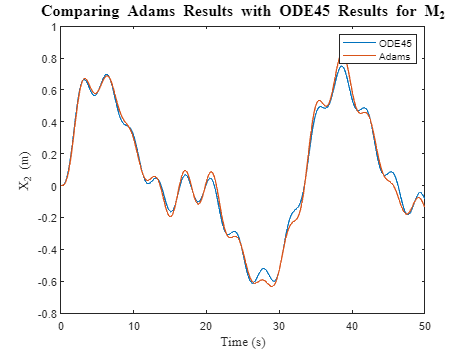


x2 = load('x_m2_adams.mat');
t2 = load('t_m2_adams.mat');
plot(t2.t_m2_adams , x2.x_m2_adams)
hold on
plot(t,x(:,2)) 
hold off
legend('ODE45','Adams')
ylabel("X_2 (m)",'fontName','Times New Roman' ,'FontSize', 12) 
xlabel("Time (s)",'fontName','Times New Roman' ,'FontSize', 12) 
title('Comparing Adams Results with ODE45 Results for M_2','fontName','Times New Roman','FontSize', 14)

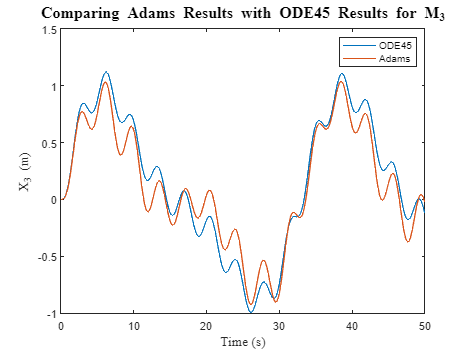


x3 = load('x_m3_adams.mat');
t3 = load('t_m3_adams.mat');
plot(t3.t_m3_adams , x3.x_m3_adams)
hold on
plot(t,x(:,3)) 
hold off
legend('ODE45','Adams')
ylabel("X_3 (m)",'fontName','Times New Roman' ,'FontSize', 12) 
xlabel("Time (s)",'fontName','Times New Roman' ,'FontSize', 12) 
title('Comparing Adams Results with ODE45 Results for M_3','fontName','Times New Roman','FontSize', 14)

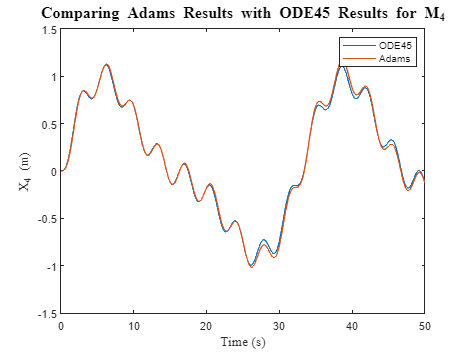


x4 = load('x_m4_adams.mat');
t4 = load('t_m4_adams.mat');
plot(t4.t_m4_adams , x4.x_m4_adams)
hold on
plot(t,x(:,4)) 
hold off
legend('ODE45','Adams')
ylabel("X_4 (m)",'fontName','Times New Roman' ,'FontSize', 12) 
xlabel("Time (s)",'fontName','Times New Roman' ,'FontSize', 12) 
title('Comparing Adams Results with ODE45 Results for M_4','fontName','Times New Roman','FontSize', 14)

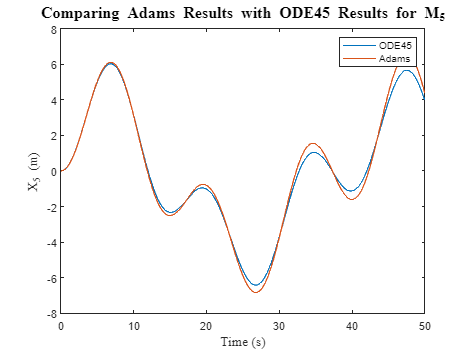


x5 = load('x_m5_adams.mat');
t5 = load('t_m5_adams.mat');
plot(t5.t_m5_adams , x5.x_m5_adams)
hold on
plot(t,x(:,5)) 
hold off
legend('ODE45','Adams')
ylabel("X_5 (m)",'fontName','Times New Roman' ,'FontSize', 12) 
xlabel("Time (s)",'fontName','Times New Roman' ,'FontSize', 12) 
title('Comparing Adams Results with ODE45 Results for M_5','fontName','Times New Roman','FontSize', 14)

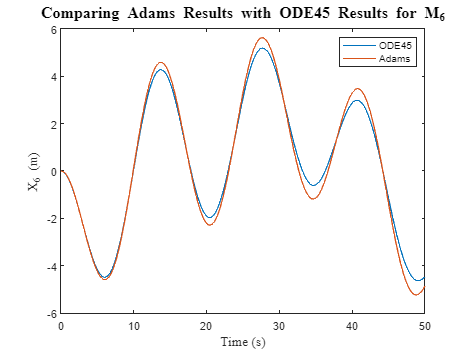



x6 = load('x_m6_adams.mat');
t6 = load('t_m6_adams.mat');
plot(t6.t_m6_adams , x6.x_m6_adams)
hold on
plot(t,x(:,6)) 
hold off
legend('ODE45','Adams')
ylabel("X_6 (m)",'fontName','Times New Roman' ,'FontSize', 12) 
xlabel("Time (s)",'fontName','Times New Roman' ,'FontSize', 12) 
title('Comparing Adams Results with ODE45 Results for M_6','fontName','Times New Roman','FontSize', 14)

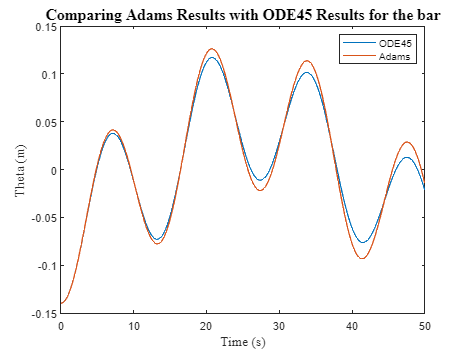


teta7 = load('theta_barr_adams.mat');
t7 = load('t_barr_adams.mat');
plot(t7.t_barr_adams , teta7.theta_barr_adams)
hold on
plot(t,-x(:,7)) 
hold off
legend('ODE45','Adams')
ylabel("Theta (m)",'fontName','Times New Roman' ,'FontSize', 12) 
xlabel("Time (s)",'fontName','Times New Roman' ,'FontSize', 12) 
title('Comparing Adams Results with ODE45 Results for the bar','fontName','Times New Roman','FontSize', 14)

## Plotting the force response of the system one by one

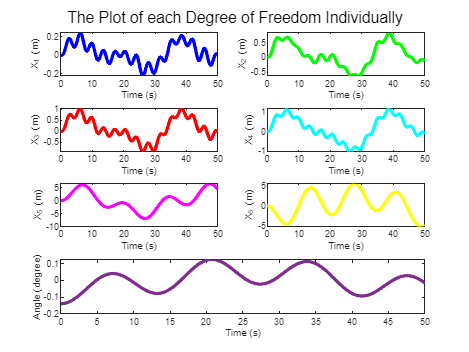

figure 
subplot(4,2,1)
plot(t,x(:,1) , 'color' , "b" , 'LineWidth' , 3) 
ylabel("X_1 (m)") 
xlabel("Time (s)") 
subplot(4,2,2)
plot(t,x(:,2) , "color" , "g" , 'LineWidth' , 3) 
ylabel("X_2 (m)") 
xlabel("Time (s)") 
subplot(4,2,3)
plot(t,x(:,3) , "color" , "r" , 'LineWidth' , 3) 
ylabel("X_3 (m)") 
xlabel("Time (s)") 
subplot(4,2,4)
plot(t,x(:,4) , "color" , "c" , 'LineWidth' , 3)
ylabel("X_4 (m)") 
xlabel("Time (s)") 
subplot(4,2,5)
plot(t,x(:,5) , "color" , "m" , 'LineWidth' , 3) 
ylabel("X_5 (m)") 
xlabel("Time (s)") 
subplot(4,2,6)
plot(t,x(:,6) , "color" , "y" , 'LineWidth' , 3) 
ylabel("X_6 (m)") 
xlabel("Time (s)") 
subplot(4,2,[7,8])
plot(t,-x(:,7) , "color" , [0.494, 0.1840, 0.556] , 'LineWidth' , 3) 
ylabel("Angle (degree)") 
xlabel("Time (s)") 
sgtitle("The Plot of each Degree of Freedom Individually")

## Defining the ode45 function

function dxdt = odefcn(t , x , M , K , C , tf , g , F) 

g = interp1(tf,g,t); % To interpolate all the values in between the poins to get a smooth graph
% I don't exactly know how that works, it was on mathworks and I used it
% the reference site is given in the appendix part

F = F*g; 

dxdt = zeros(14 , 1); 

xx = [x(1) ; x(2) ; x(3) ; x(4) ; x(5) ; x(6) ; x(7)] ; 

xdot = [x(8) ; x(9) ; x(10) ; x(11) ; x(12) ; x(13) ; x(14)]; 

xddot = (F - K * xx - C * xdot); 


dxdt(1) = x(8); 

dxdt(2) = x(9); 

dxdt(3) = x(10); 

dxdt(4) = x(11); 

dxdt(5) = x(12); 

dxdt(6) = x(13); 
 
dxdt(7) = x(14);


dxdt(8) = (xddot(1))/M(1,1);  

dxdt(9) = (xddot(2))/M(2,2); 

dxdt(10) = (xddot(3))/M(3,3); 

dxdt(11) = (xddot(4))/M(4,4); 

dxdt(12) = (xddot(5))/M(5,5); 

dxdt(13) = (xddot(6))/M(6,6); 

dxdt(14) = (xddot(7))/M(7,7);
 

end